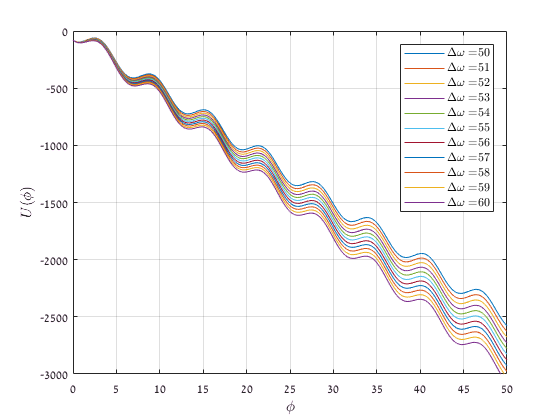

% Washboard Potential analysis
% Shay Kricheli, 2018
clc; clear;
t = 0:0.1:50;
B = 80;
for delta = 70 : 80
    h = strcat('$\Delta\omega =$ ',num2str(delta));
    plot(t, -delta*t - B* cos(t),'DisplayName',h);
    hold on;
end
h = legend('show','Location','northeast'); set(h,'Interpreter','latex');
h = ylabel('$U (\phi)$'); set(h,'Interpreter','latex');
h = xlabel('$\phi$'); set(h,'Interpreter','latex');
grid;
axis([0 50 -3000 0]);
print('washboard','-dmeta','-r3000') % save photo